# GPS Demo - Gator Summer 2022

### REV A

GPS Demo to drive Gator from Camp Bravo to Camp Charlie loop and back to Camp Bravo in Parcel B.

%%% Path Declaration
addpath(...
    "ACT\",...
    "SENSE\",...
    "SETUP\",...
    "SHUTDOWN\",...
    "THINK\",...
    "TESTING\",...
    "SIMULATION\",...
    "RTK_GPS\")
disp("FOLDER PATHS ADDED")

FOLDER PATHS ADDED


Found Start 1


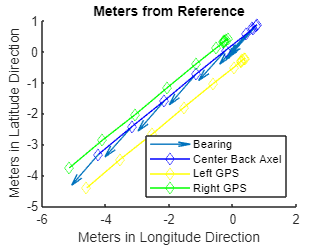

%%% SETUP GPS MAP 
GPStoFront=0.762;% midpoint GPS to front of car
GPStoback=1;% midpoint GPS to back of car
FronttoBack=GPStoback+GPStoFront;
[waypoints,lat1new,lon1new,lat2new,lon2new, middlelatref,middlelonref]=ConfigureWaypoint("RTK_GPS\GPS_Right_Forest_True.ubx","RTK_GPS\GPS_Left_Forest_True.ubx",GPStoback);

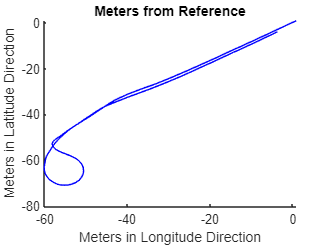

 clf
 start=1;
 section=size(lat1new,2);
 hold on
  title("Meters from Reference")
     xlabel('Meters in Longitude Direction') 
    ylabel('Meters in Latitude Direction') 
 plot(waypoints(start:section,2),waypoints(start:section,1),'-b');
 hold off

%%%simulation
% Variable Setup
clf
wayStep=15;
 start=wayStep-1;
controlFlag=1;
gpsData = struct( ...
             "lon1", lon1new(1,start),...
             "lat1", lat1new(1,start),...
             "lon2", lon2new(1,start),...
             "lat2", lat2new(1,start)...
             );
% Main Loop
hold on
title("Meters from Reference")
 xlabel('Meters in Longitude Direction') 
ylabel('Meters in Latitude Direction') 
plot(waypoints(wayStep:end,2),waypoints(wayStep:end,1),'-bd'); % add '-bd' to add points
[CurrentPosHead]= ReferencePoint(middlelatref,middlelonref,gpsData,GPStoback);
plot(CurrentPosHead.X,CurrentPosHead.Y,'-gd')

while (controlFlag < 200)           % loop for number of elements in t
    % Think
    [motorControls, wayStep]=thinkPathB2C(CurrentPosHead, waypoints, wayStep,FronttoBack);
    % End-of-path checker
   if wayStep>size(waypoints,1)
        disp("END")
        break 
    end
    [CurrentPosHead] = SimulateSense(CurrentPosHead,motorControls,FronttoBack);
    plot(CurrentPosHead.X,CurrentPosHead.Y,'-rd')
    text(CurrentPosHead.X,CurrentPosHead.Y,num2str(motorControls.steer,2))
    controlFlag=controlFlag+1;
end 

END


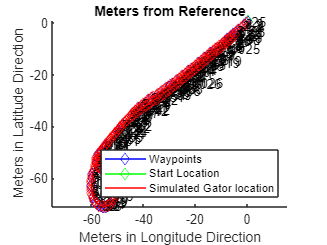

 legend({'Waypoints','Start Location','Simulated Gator location'},'Location','southeast')
axis equal
hold off

%setupGPSDemo(Mega,GPS1,GPS2);
objects1 = setupGPSDemo('COM7','COM5','COM6');

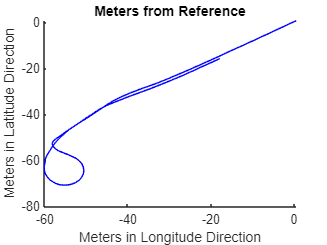

%%% MAIN
%%%simulation
% Variable Setup
clf
wayStep=15;
 start=wayStep-1;
 section=wayStep+120;
controlFlag=1;
%plotting
hold on
title("Meters from Reference")
 xlabel('Meters in Longitude Direction') 
ylabel('Meters in Latitude Direction') 
plot(waypoints(wayStep:section,2),waypoints(wayStep:section,1),'-b');
plot(CurrentPosHead.X,CurrentPosHead.Y,'-g')


%inital voltage
motorControls.throttle=0;
motorControls.steer=0;
oldmotorControls  = struct( ...
    "throttle", [],...
    "steer",[]);
actGPS(objects1.Mega, motorControls,oldmotorControls)

Unable to resolve the name objects1.Mega.

oldmotorControls=motorControls

disp("Turn on Linear Actuators") 
pause
% Main Loop
while (controlFlag > 0)           % loop for number of elements in t
    % Sense
    senseobjects = sense(objects1);

    % Think
    [CurrentPosHead]= ReferencePoint(middlelatref,middlelonref,senseobjects.gpsData,GPStoback)
     [motorControls, wayStep]=thinkPathB2C(CurrentPosHead,waypoints, wayStep,FronttoBack);
    
    % Act
    actGPS(objects1.Mega, motorControls,oldmotorControls);

    % End-of-path checker
    if wayStep>size(waypoints,1)
        disp("END")
        motorControls.throttle=-1;
        actGPS(objects1.Mega, motorControls,oldmotorControls)
        break 
    end
    % Update MotorControls
    oldmotorControls=motorControls; 

    %plot
    plot(CurrentPosHead.X,CurrentPosHead.Y,'-g')
    controlFlag=controlFlag+1;
end 
axis equal
hold off

%%% SHUTDOWN
clear